## **环境交互测试实验1：获得森林2D区域并将其离散化用于无人机搜索**

%% 添加必要的路径
run('path_add.m')
clear,clc

% 加载数据
filename = "Forest_data.mat";
% 使用exist函数检查文件是否存在  
if exist(filename, 'file') == 2  
    load Forest_environment\Forest_data.mat 
else  
    run("Forest_environment\Forest_generate.m")
    load Forest_environment\Forest_data.mat
end

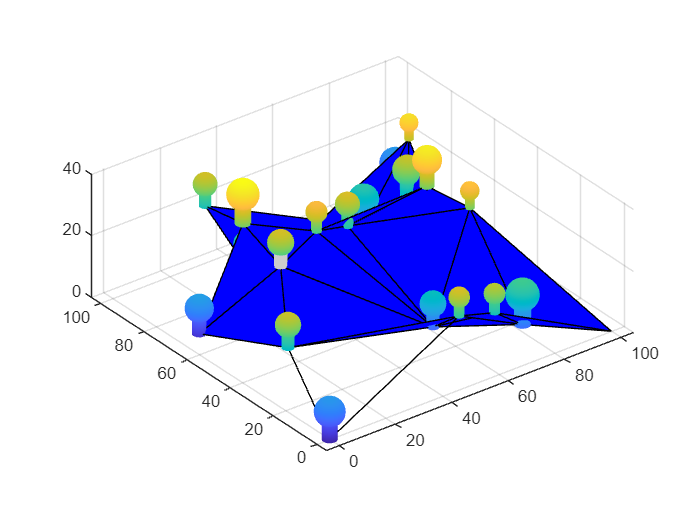

figure
hold on
draw_trees(trees, field_tree)
hold off

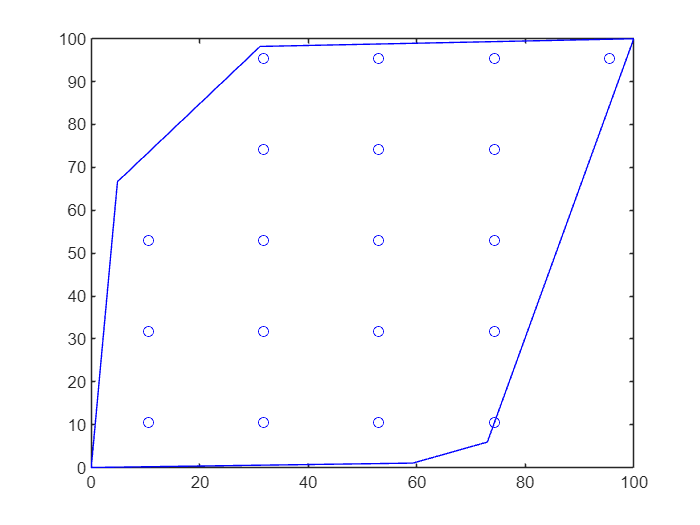

% 找到各个树的2D位置
positions_2D = field_tree.positions(:,1:2);
% 找到树的外接凸多边形坐标
hullpositions_2D = findConvexHull(positions_2D);
r_s = 30; % 无人机搜索半径
task_region = region(hullpositions_2D(1:end-1,:),r_s);
task_region = task_region.region_meshing; % 区域离散化
task_region.region_show;

test_region = region(hullpositions_2D(1:end-1,:),10); % 该区域用于测试算法的效果
test_region = test_region.region_meshing;
altitude_Cruising = field_tree.zmax;  % 巡航海拔高度

% 利用蚁群系统规划路线
num_e = 20;
num_t = 60;
num_totest = 10;
[ants_best,allow,tao_t,tao_e,ant_e,ant_t] = ...
    Rapid_PP_TSP(task_region.points_for_drone,num_e,num_t,num_totest);

第1次测试(TSP问题)
第2次测试(TSP问题)
第3次测试(TSP问题)
第4次测试(TSP问题)
第5次测试(TSP问题)
第6次测试(TSP问题)
第7次测试(TSP问题)
第8次测试(TSP问题)
第9次测试(TSP问题)
第10次测试(TSP问题)


% 初始化无人机
pointstoflys=[task_region.points_for_drone,altitude_Cruising*ones(size(task_region.points_for_drone,1),1)];
max_speed = 10;
max_range = 60;
max_altitude = 310;
max_power = 2000;
max_load = 25;
k_up = 0.05;
k_down = 0.01;
k_around = 0.03;
dt = 0.1;
uav_0 = uav(max_speed,max_range,max_altitude,max_power,max_load,k_up,k_down,k_around,dt);
uav_0 = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);

% 飞行并找到燃烧的树木
% 找到最短的蚁群路径
ant_tofly = ants_best(1);
for i=2:length(ants_best)
    if ants_best(i).distance < ant_tofly.distance
        ant_tofly = ants_best(i);
    end
end
for i=1:length(ant_tofly.positions)
    uav_0 = uav_0.FlyToNextPoint_flexible(pointstoflys(ant_tofly.positions(i),:),[],[],trees,field_tree);
end

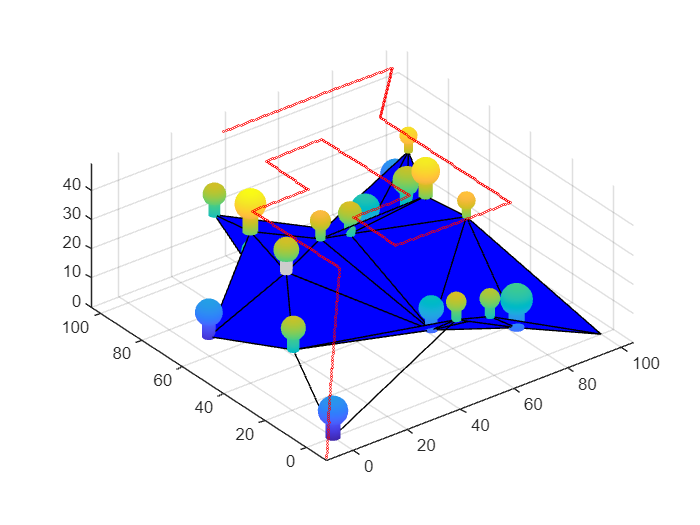

% 让我们将环境和轨迹简单的画出来吧
figure
hold on
draw_trees(trees, field_tree)
scatter3(uav_0.position(:,1),uav_0.position(:,2),uav_0.position(:,3),'red',SizeData=1)
hold off

% 计算各评价指标，分析算法效果
polygon = task_region.profile; % 四边形
path = uav_0.position(1:5:end,1:2); % 无人机路径
radius = 60; % 无人机搜索半径

[coverageRate, ~] = calculateCoverageAndRedundancy(polygon, path, radius);
pathLength = calculatePathLength(path);
fprintf('覆盖率: %.2f%%\n', coverageRate * 100);

覆盖率: 100.00%


fprintf('路程长度: %.2f%\n', pathLength);

路程长度: 3342.22

% 与其他算法进行比较
% 经典蚁群算法
[Routes,lengths]=ant_colony_for_drones(task_region.points_for_drone,num_t+num_e,num_totest);
% 找到最短的蚁群路径
min_length = lengths(1);
min_route = Routes(1,:);
for i=2:length(lengths)
    if lengths(i) < min_length
        min_length = lengths(i);
        min_route = Routes(i,:);
    end
end
uav_1 = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);
for i=1:length(ant_tofly.positions)
    uav_1 = uav_1.FlyToNextPoint_flexible(pointstoflys(min_route(i),:),[],[],trees,field_tree);
end
% 计算各评价指标，分析算法效果
path1 = uav_1.position(1:5:end,1:2); % 无人机路径
radius = 60; % 无人机搜索半径
[coverageRate, ~] = calculateCoverageAndRedundancy(polygon, path1, radius);
pathLength = calculatePathLength(path1);
fprintf('覆盖率: %.2f%%\n', coverageRate * 100);

覆盖率: 100.00%


fprintf('路程长度: %.2f%\n', pathLength);

路程长度: 3581.38

% 蛇形搜索算法
snakePath = generateSnakePath(task_region.points_for_drone);
uav_1 = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);
for i=1:length(ant_tofly.positions)
    uav_1 = uav_1.FlyToNextPoint_flexible([snakePath(i,:),altitude_Cruising],[],[],trees,field_tree);
end
% 计算各评价指标，分析算法效果
path1 = uav_1.position(1:5:end,1:2); % 无人机路径
radius = 60; % 无人机搜索半径
[coverageRate, ~] = calculateCoverageAndRedundancy(polygon, path1, radius);
pathLength = calculatePathLength(path1);
fprintf('覆盖率: %.2f%%\n', coverageRate * 100);

覆盖率: 100.00%


fprintf('路程长度: %.2f%\n', pathLength);

路程长度: 3098.87

% 燕群算法
[Shortest_Route,Shortest_Length]=swallow_for_drones(task_region.points_for_drone,num_t+num_e,num_totest);
uav_1 = uav(max_speed,max_range,max_altitude,max_power*2,max_load,k_up,k_down,k_around,dt);
uav_1 = uav_1.current_properties_reset(8/10*max_speed,0,max_power*2,max_load/2,[-10,-10,1]);
for i=1:length(ant_tofly.positions)
    uav_1 = uav_1.FlyToNextPoint_flexible(pointstoflys(Shortest_Route(i),:),[],[],trees,field_tree);
end
% 计算各评价指标，分析算法效果
path1 = uav_1.position(1:5:end,1:2); % 无人机路径
radius = 60; % 无人机搜索半径
[coverageRate, ~] = calculateCoverageAndRedundancy(polygon, path1, radius);
pathLength = calculatePathLength(path1);
fprintf('覆盖率: %.2f%%\n', coverageRate * 100);
fprintf('路程长度: %.2f%\n', pathLength);